# Nonholnomic Kinematics

Objective: This script solves for the kinematic equations and uses the resulting V and w to plot the robot trajectory

Helper Functions used in this exercise:

- *plot_robot *plots the robot,  visual representation (blue arrow) of the velocity of (1) right wheel, (2) left wheel, and (3) overall velocity, and the trajectory the robot will move (red line) based on the solved control inputs.  

Exercise:

You will solve for the control inputs for the Create using the kinematic equations. 

Robot parameters that are Inputs to kinematic equations. 

L = 0.26; % Distance between wheels in meters
r = 0.05; % Wheel radius in meters

Complete the code to 

- Define the commanded wheel rotational speeds

- Use the kinmatic equations to solve for the control inputs for the create: Forward/backward velocity (v) and angular velocity w. 

**COMPLETE THE CODE BELOW**

%1. Define Wheel rotational speed (/s) for left and right wheels 
u_l =2*pi; %Insert your code here
u_r =pi; % Insert your code here
maxWheelSpeed = 10; 

%2. Solve kinematic equations

% Using the robot parameters, define the A matrix and assign to the variable A.  
% Solve for V and w using the matrix form. 

A = [r/2, r/2; r/L, -r/L]; %Insert your code here
robotVelocities = A*[u_r;u_l]; %Insert your code here
V = robotVelocities(1); %Insert your code here
omega = robotVelocities(2); %Insert your code hereUsng the kinematic equations,  plot the resulting trajectory of the robot. 

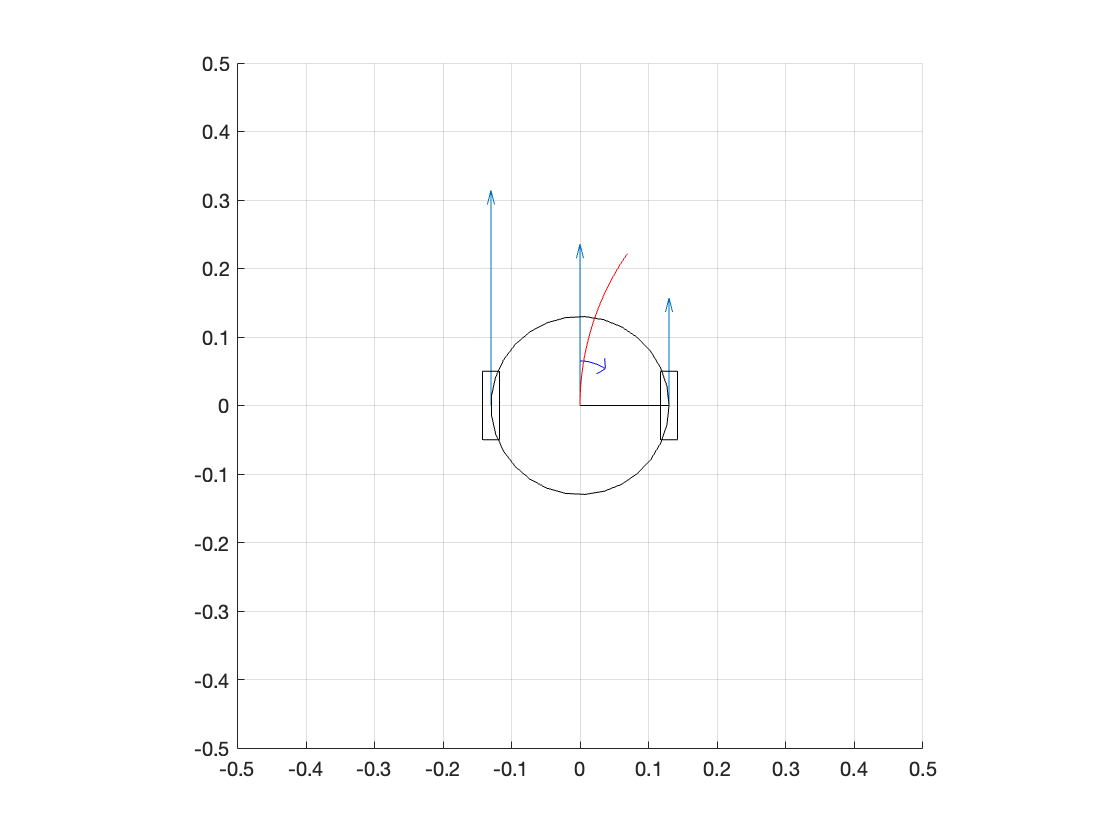

%Plot
plot_title = "Robot Trajectory"; 

plot_robot(u_r,u_l,V,omega,L,r, plot_title);

Expected Results:  This script plotsthe robot, visual representation (blue arrow) of the velocity of (1) right wheel, (2) left wheel, and (3) overall velocity, and the trajectory the robot will move (red line) based on the solved control inputs.  

Check your Comprehension: Try different values for $u_l$ and $u_r$, and update the plot to see how the robot and its wheels velocities will be updated. The red line shows the path the robot will take for the next 1 second given these controls.